x = 1:5

x =      1     2     3     4     5


f = [ 14 2 17 23 13]

f =     14     2    17    23    13


dif_div(x,f)

ans =    14.0000  -12.0000   13.5000   -6.0000    1.2083
    2.0000   15.0000   -4.5000   -1.1667       NaN
   17.0000    6.0000   -8.0000       NaN       NaN
   23.0000  -10.0000       NaN       NaN       NaN
   13.0000       NaN       NaN       NaN       NaN



Nf=@(X) Newton_interpolare(x,f,X)

Nf = function_handle with value:
    @(X)Newton_interpolare(x,f,X)


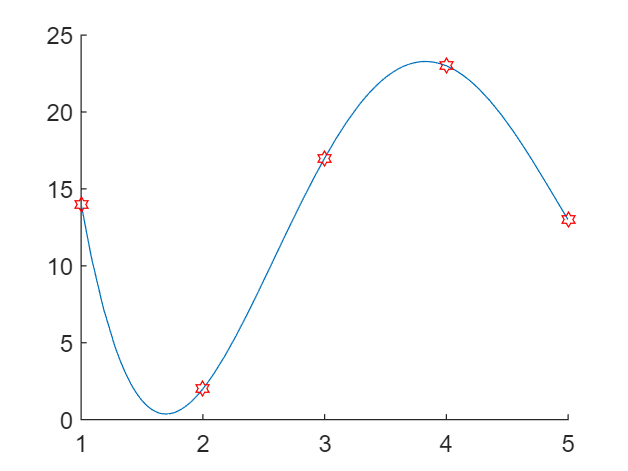


clf; hold on;
fplot(Nf,[1,5])
plot(x,f,'hr')

x=[0 3]

x =      0     3


f=[10 13]

f =     10    13


df=[5 7]

df =      5     7



X=linspace(0,3,1000)

X =          0    0.0030    0.0060    0.0090    0.0120    0.0150    0.0180    0.0210    0.0240    0.0270    0.0300    0.0330    0.0360    0.0390    0.0420    0.0450    0.0480    0.0511    0.0541    0.0571    0.0601    0.0631    0.0661    0.0691    0.0721    0.0751    0.0781    0.0811    0.0841    0.0871    0.0901    0.0931    0.0961    0.0991    0.1021    0.1051    0.1081    0.1111    0.1141    0.1171    0.1201    0.1231    0.1261    0.1291    0.1321    0.1351    0.1381    0.1411    0.1441    0.1471


[H,dH]=Hermite_interpolare(x,f,df,X)

H =    10.0000   10.0150   10.0299   10.0447   10.0594   10.0740   10.0886   10.1031   10.1174   10.1317   10.1460   10.1601   10.1742   10.1881   10.2020   10.2159   10.2296   10.2432   10.2568   10.2703   10.2837   10.2970   10.3103   10.3234   10.3365   10.3495   10.3625   10.3753   10.3881   10.4008   10.4134   10.4259   10.4384   10.4507   10.4630   10.4753   10.4874   10.4995   10.5115   10.5234   10.5352   10.5469   10.5586   10.5702   10.5817   10.5932   10.6046   10.6159   10.6271   10.6382


dH =     5.0000    4.9720    4.9441    4.9162    4.8884    4.8606    4.8329    4.8053    4.7777    4.7502    4.7227    4.6953    4.6680    4.6407    4.6135    4.5863    4.5592    4.5322    4.5052    4.4783    4.4515    4.4247    4.3979    4.3713    4.3446    4.3181    4.2916    4.2652    4.2388    4.2125    4.1862    4.1600    4.1339    4.1078    4.0818    4.0558    4.0299    4.0041    3.9783    3.9526    3.9270    3.9014    3.8758    3.8504    3.8250    3.7996    3.7743    3.7491    3.7239    3.6988


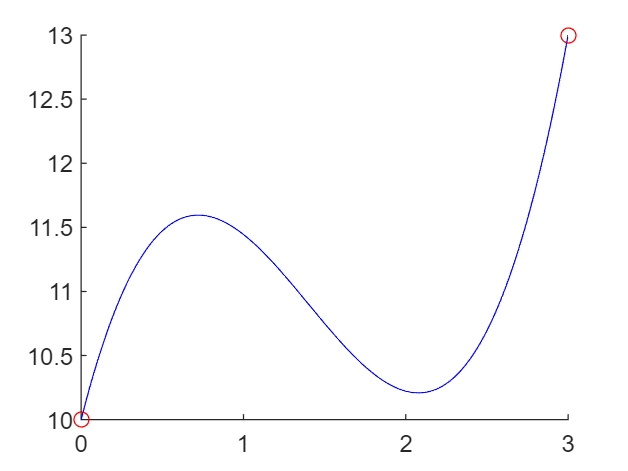

clf; hold on;
plot(X,H,'-b');
plot(x,f,'or');

dH([1,end])

ans =     5.0000    7.0000


t = [0 3 5 8 13]

t =      0     3     5     8    13


d = [0 225 383 623 993]

d =      0   225   383   623   993


v = [75 77 80 74 72]

v =     75    77    80    74    72



X=linspace(0,13,1000)

X =          0    0.0130    0.0260    0.0390    0.0521    0.0651    0.0781    0.0911    0.1041    0.1171    0.1301    0.1431    0.1562    0.1692    0.1822    0.1952    0.2082    0.2212    0.2342    0.2472    0.2603    0.2733    0.2863    0.2993    0.3123    0.3253    0.3383    0.3514    0.3644    0.3774    0.3904    0.4034    0.4164    0.4294    0.4424    0.4555    0.4685    0.4815    0.4945    0.5075    0.5205    0.5335    0.5465    0.5596    0.5726    0.5856    0.5986    0.6116    0.6246    0.6376


[H,dH]=Hermite_interpolare(t,d,v,X)

H =          0    0.9772    1.9566    2.9383    3.9219    4.9075    5.8949    6.8840    7.8747    8.8668    9.8603   10.8551   11.8510   12.8481   13.8461   14.8450   15.8447   16.8452   17.8463   18.8480   19.8502   20.8528   21.8558   22.8590   23.8625   24.8662   25.8699   26.8738   27.8776   28.8813   29.8850   30.8885   31.8917   32.8948   33.8975   34.9000   35.9020   36.9037   37.9049   38.9057   39.9059   40.9057   41.9048   42.9034   43.9014   44.8987   45.8954   46.8914   47.8867   48.8813


dH =    75.0000   75.1813   75.3527   75.5143   75.6666   75.8097   75.9440   76.0696   76.1869   76.2961   76.3975   76.4913   76.5777   76.6570   76.7294   76.7951   76.8544   76.9074   76.9545   76.9957   77.0313   77.0615   77.0865   77.1065   77.1216   77.1321   77.1382   77.1399   77.1375   77.1312   77.1211   77.1073   77.0901   77.0696   77.0459   77.0192   76.9897   76.9574   76.9225   76.8852   76.8455   76.8036   76.7597   76.7138   76.6661   76.6167   76.5656   76.5131   76.4592   76.4040


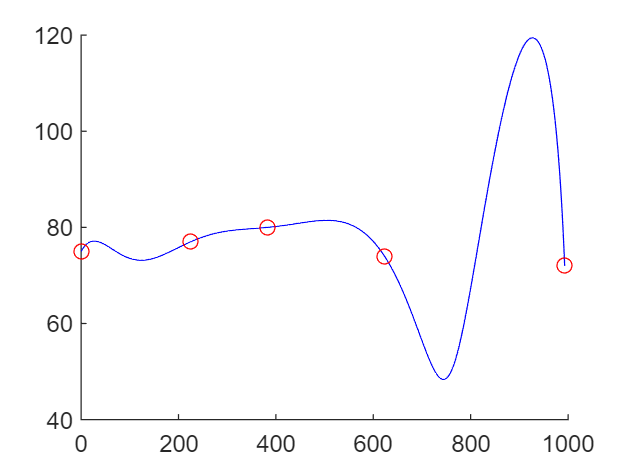

clf; hold on;
plot(H,dH,'-b');
plot(d,v,'or');